# Homework1

Lin Zhao, Ning Wang

## Exercise 1:

### Open loop control

1.1. Find the equilibrium points corresponding to the constant input $u^*$. You don’t need to find explicit expressions for the equilibrium points; it is enough that you find an expression that relates the equilibrium points and the corresponding constant input. 

Solution: 

By setting


$$\begin{cases}{ f_1=x_2=0\\
f_2=-x_1-0.2x_2+x_3^2=0\\
f_3=-1.6(1-x_1)x_3+u^*=0 \end{cases}$$


we can get


$$\begin{cases}x_{2}=0\\
x__{1}=x_{3}^2\\
x_{3}-x_{3}^{3}=\frac{u^{*}}{2.6}  \end{cases}$$


1.2.  Plot $u^*$ as a funcion of $x_1^*$. Remember that $0 \leq x_{1} \leq 1$. Consider $u^{*}=0.8$. What equilibrum points $x_1^*$ does that correspond to? Are they stable or unstable?

Solution: Plot u* as a function of $x_{1}^{*}$

when $x_{3}>0$


$$u^*=2.6\cdot \sqrt{x_{1}}(1-x_{1})$$


else if $x_{3}<=0$


$$u^*=2.6\cdot \sqrt{x_{1}}(1-x_{1})$$


which is shown as the following figure.

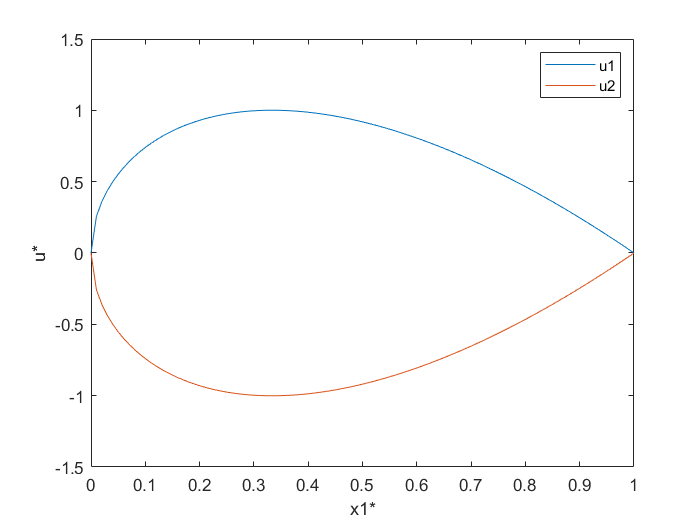

clear
clc

x1=0:0.01:1;

u=2.6.*(1-x1).*x1.^0.5;

figure(1)
title('u*VSx1*’')
plot(x1,u); 
hold on
plot (x1,-u); legend('u1','u2'); xlabel('x1*');ylabel('u*');

when u*=0.8


$$x_{3}^{*}(1-x_{3}^{*2})=\frac{0.8}{2.6}$$



$$x_{3}^{*}(1-x_{1}^{*})=\frac{0.8}{2.6}$$



$$x_{1}^{*}=1-\frac{0.8}{2.6x_{3}^{*}}$$


so $x_{1}^{*}$ correspond to the value of $x_{3}^{*}$.

when u*=0.8


$$x_{3}^{*3}-x_{3}^{*}+\frac{0.8}{2.6}=0$$


x3=roots([1 0 -1 0.8/2.6])

x3 =    -1.1282
    0.7773
    0.3509



$$x_{1}^{*}=x_{3}^{*2}$$


so  $x_{1}^{*}$ does correspond to the value of $x_{3}^{*}$.

x1=x3.^2

x1 =     1.2727
    0.6041
    0.1231


Because x1 belong to [0,1] , so 

x1=          0.6041  and        0.1231  

Stable Analysis:  Jocobian matrix 


$$M=\left[ \begin{array}{ccc} 0 & 1& 0\\ -1&-0.2 & 2*x_3\\ 2.6*x_3 & 0 & -2.6+2.6*x_1 \end{array}  \right ]

$$


The Jocobian matric are M1 and M2 separately.

x31=    0.7773;
x32=    0.3509;
x11=    0.6041;
x12=    0.1231;

M1=[0  1   0;  -1   -0.2   2*x31;  2.6*x31  0  -2.6+2.6*x11]

M1 =          0    1.0000         0
   -1.0000   -0.2000    1.5546
    2.0210         0   -1.0293


M2=[0  1   0;  -1   -0.2   2*x32;  2.6*x32  0  -2.6+2.6*x12]

M2 =          0    1.0000         0
   -1.0000   -0.2000    0.7018
    0.9123         0   -2.2799


[V1,D1]=eig(M1);
[V2,D2]=eig(M2);


The equilibrium point(0.6041,  0,  0.7773)  and (0.1231, 0,  0.3509)

The first  egienvalue are [   -0.9995 + 1.3212i,    -0.9995 - 1.3212i,           0.7697], because 0.7697>0, so this equilibrium is unstable.

The second egienvalue are [   -2.1573,    -0.1613 + 0.8567i,    -0.1613 - 0.8567i], and all the Re[lamda]<0, so this equilibrium is stable.

1.3. Simulate the open loop system (with constant input $u^{*}=0.8$) for different initial states $x(0)$. We can limit the investigation on to initial states of the form $x(0) = [x_1(0),0,\sqrt{x_1(0)}]$ and vary $x_1(0)$ between 0 and 1. For any stable equilibrium, what is the region of attraction (in terms of $x_1(0)$)?  

Solution:

when vary the value of x0 between (-1, 0), we  can get the following figure: 

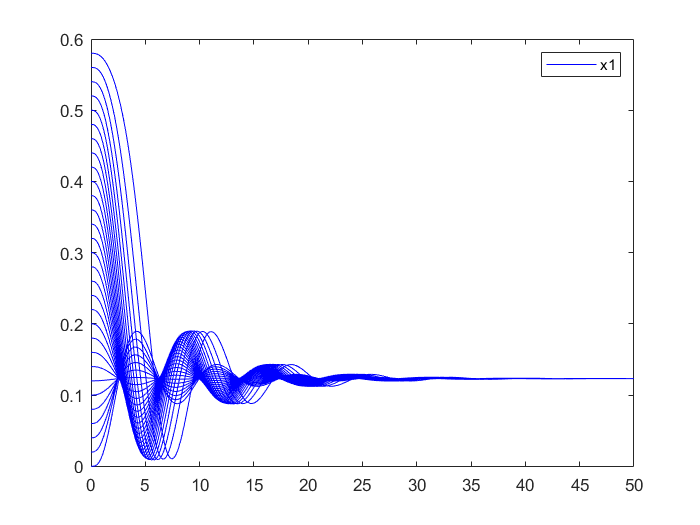

% x0=[0,0,0].';
% tspan=[0,100];
% sol=ode15s(@systemt,tspan,x0);
% t=linspace(0,10,100);
% x=deval(sol,t);
% figure(2)
% plot(t,x(1,:))
% legend('x1')
% xlabel('u*')
% ylabel('x1')


f1=@(x1,x2,x3) x2;
f2=@(x1,x2,x3)-x1-0.2*x2+x3^2;
f3=@(x1,x2,x3)-2.6*(1-x1)*x3+0.8;
% The state Space Equation
f=@(x1,x2,x3)[f1(x1,x2,x3);f2(x1,x2,x3);f3(x1,x2,x3)];
tspan = [0.0, 50.0];
% p1 = [0.3, -1, 1, 0.37, 1.2];
% p2 = [0.3, -1, 0.9, 0.5, 1];

figure(2)

for i=0:0.02:0.59
    x0 = [i, 0.0, i^0.5]';
%     
    sol1 = ode45(@(t,x) f(x(1),x(2),x(3)), tspan, x0);
    t = 0:0.1:tspan(end);
    x1 = deval(sol1,t);
    plot(t,x1(1,:),'-b');
    
xlim([0.0 50.0])
ylim([-0.001 0.6])
    hold on
    legend('x1')
end



% sol2 = ode45(@(t,x)ode_duffing(t,x,p2), tspan, x0);
% t = 0:0.1:tspan(end);
% x1 = deval(sol1,t);
% x2 = deval(sol2,t);
% figure(2)
% plot(t,x1(1,:));
% hold on
% plot(t,x1(2,:));
% hold on
% plot(t,x1(3,:));
% legend('x(1)','x(2)','x(3)')

When u*=0.8, the equilibrium is shown as the above figure, the state is stabeled at the equalibrium point.

when the x1(0) bigger than the 0.59, the matlab could not solve the equation, because the equation do not converge, so the region of attraction is [0 0.59]

### State Feedback Control

The controller of the system, to control x*=0.6


x1= 0.6;
x33=0.6^0.5;
x34=-0.6^0.5;
M31=[0  1   0;  -1   -0.2   2*x33;  2.6*x33  0  -2.6+2.6*x1];
M32=[0  1   0;  -1   -0.2   2*x34;  2.6*x34  0  -2.6+2.6*x1];
[V3,D3]=eig(M31);
[V4,D4]=eig(M32);
x1s=0.6;
x3s1=x1s^0.5; %x3*
x3s2=-x1s^0.5;
u1s=2.6*(1-x1s)*x3s1;
u2s=2.6*(1-x1s)*x3s2;
b2=0.2;
b31=2*x3s1;
b32=2*x3s2;
c11=2.6*x3s1;
c12=2.6*x3s2;
c3=2.6*(x1s-1);
c13=2.6;


f=@(x,u)[x(2,:);-x(1,:)-0.2*x(2,:)+x(3,:)^2;-2.6*(1-x(1,:))*x(3,:)+u];
k1=0.1;

k2=0.1;
k3=1;
phi=@(x)-k1*(x(1,:)-0.6)-k2*(x(2,:))-k3*(x(3,:)-0.6^0.5)+u2s;
%phi=@(x)-k1*(x(1,:)-0.6)-k2*(x(2,:))-k3*(x(3,:))%+u2s;
tf=50;
x0=[1;1;1];
% figure(4)
% ode45(@(t,x)f(x,phi(x)),[0,tf],x0)
% 
% xlabel('t')
% ylabel('x')
% legend('x1','x2','x3')



The eignvalue of the transformed system

A1=[0 1 0; -1 -b2 b31; c11 0 c3];
A2=[0 1 0; -1 -b2 b32; c12 0 c3];
e1=eig(A1);
e2=eig(A2);

%%
syms x [3,1]
syms u
fs = [x2; -x1-b2*x2+b31*x3 + x3^0.5; c11*x1+c3*x3+c13*x1*x3+u];
%A = double(subs(jacobian(fs,x),x,[0;0;0]));
A=[0 1 0; -1 -b2 b31; c11 0 c3];
B = [0;0;1];
f1 = @(x1,x2,x3) x2;
f2 = @(x1,x2,x3) -x1-b2*x2+b31.*x3 + x3.^2;
f3 = @(x1,x2,x3,u)  c11*x1+c3*x3+c13.*x1.*x3+u;
f = @(x1,x2,x3,u)[f1(x1,x2,x3);f2(x1,x2,x3);f3(x1,x2,x3,u)];
u_open_loop = 0;
[X1,X2,X3] = meshgrid(linspace(-1,1,18),linspace(-1,1,18),linspace(-1,1,18));
F1 = f1(X1,X2,X3);
F2 = f2(X1,X2,X3);
F3= f3(X1,X2,X3,u_open_loop);
mag = sqrt(F1.^2+F2.^2+F3.^2);
Q = eye(3);
R = 1;
K = lqr(A,B,Q,R);
u_lin = @(x1,x2,x3)-K(1)*x1-K(2)*x2-K(3)*x3;
% 
% figure(4)
% %quiver(X1,X2,x3, F1./mag,F2./mag,F3./mag,0.5)
% mesh(X1,X2,X3)
% streamslice(X1,X2,X3,F1,F2,F3)
% set(gca,'XLim',[-1,1],'YLim',[-1,1],'ZLim',[-1,1]);

### Linear Control

2.1. Linearize the system around the origin (in the transformed variables $y$ and $v$). A complete answer shall provide the linearized form of the system written as variables, and numerical values of the linearized system.

Solution:The linearized system can be written as:


$$A =   \pmatrix{0 & 1 & 0 \cr -1 & -b_{2} & b_{3}+2y_{3} \cr c_{1}+c_{13}y_{3} & 0 & c_{3}+c_{13}y_{1}}$$



$$B=\pmatrix{0 \cr 0 \cr 1}$$



$$\dot{y}=Ay+Bv$$


Then we can get the system written as variables:


$$A =   \pmatrix{0 & 1 & 0 \cr -1 & -b & 2x_{3}^{*}+2y_{3} \cr cx_{3}^{*}+cy_{3} & 0 & c(x_{1}^{*}-1)+cy_{1}}$$



$$B=\pmatrix{0 \cr 0 \cr 1}$$



$$\dot{y}=Ay+Bv$$


Given $x_{1}^{*}=0.6$


$$x_{3}^{*}=\pm\sqrt{0.6}$$


Then plug in the numerical values:


$$A =   \pmatrix{0 & 1 & 0 \cr -1 & -0.2 & 2\sqrt{0.6}+2y_{3} \cr 2.6\sqrt{0.6}+2.6y_{3} & 0 & -1.04+2.6y_{1}}$$



$$B=\pmatrix{0 \cr 0 \cr 1}$$


or


$$A =   \pmatrix{0 & 1 & 0 \cr -1 & -0.2 & -2\sqrt{0.6}+2y_{3} \cr -2.6\sqrt{0.6}+2.6y_{3} & 0 & -1.04+2.6y_{1}}$$



$$B=\pmatrix{0 \cr 0 \cr 1}$$



$$\dot{y}=Ay+Bv$$


Around the origin they are:


$$A =   \pmatrix{0 & 1 & 0 \cr -1 & -0.2 & 2\sqrt{0.6} \cr 2.6\sqrt{0.6} & 0 & -1.04}$$



$$B=\pmatrix{0 \cr 0 \cr 1}$$


or


$$A =   \pmatrix{0 & 1 & 0 \cr -1 & -0.2 & -2\sqrt{0.6} \cr -2.6\sqrt{0.6} & 0 & -1.04}$$



$$B=\pmatrix{0 \cr 0 \cr 1}$$



$$\dot{y}=Ay+Bv$$


Around the origin they are:


$$A =   \pmatrix{0 & 1 & 0 \cr -1 & -0.2 & 2\sqrt{0.6} \cr 2.6\sqrt{0.6} & 0 & -1.04}$$



$$B=\pmatrix{0 \cr 0 \cr 1}$$


Rank(A,B)=3, so it is controllable.

% a1=[0 1 0; -1 -0.2 2*0.6^0.5; 2.6*0.6^0.5 0 -1.04];
% b1=[0;0;1];
% A1=ctrb(a1,b1);
% rank(A1);

or


$$A =   \pmatrix{0 & 1 & 0 \cr -1 & -0.2 & -2\sqrt{0.6} \cr -2.6\sqrt{0.6} & 0 & -1.04}$$



$$B=\pmatrix{0 \cr 0 \cr 1}$$


Rank(A, B)=3, so it is controllable.

% a2=[0 1 0; -1 -0.2 -2*0.6^0.5; -2.6*0.6^0.5 0 -1.04];
% b2=[0;0;1];
% A2=ctrb(a2,b2);
% rank(A2);

For $x_{3}^{*}=\sqrt{0.6}$:

2.2. Design a controller using methods from linear control, for example pole placement ( `place(A,B,P) `) or LQR control ( `lqr(A,B,Q,R) `). Choose/tune the controller parameters so that $|u(t)| \leq 2$ when $x(0)=0$. A complete solution shall include the key steps of derivation of the controller and the numerical values of the controller.

Solution: We list the functions f1, f2 and f3, and calculate the Jacobian matrix A. Then, using function place(A,B,P), the controller gain Kv is calculated.

The poles we used are [-1.3;-0.4-0.9i;-0.4+0.9i].

syms x [3,1]
syms u
f1 = @(x1,x2,x3) x2;
f2 = @(x1,x2,x3) -x1-0.2*x2+2*sqrt(0.6).*x3 + x3.^2;
f3 = @(x1,x2,x3,u)  2.6*sqrt(0.6)*x1+2.6*(0.6-1)*x3+2.6.*x1.*x3+u;
f = @(x1,x2,x3,u)[f1(x1,x2,x3);f2(x1,x2,x3);f3(x1,x2,x3,u)];
A = double(subs(jacobian(f,x),x,[0;0;0]));
B = [0;0;1];
u0 = 2.6*(1-0.6)*0.6^0.5;
P = [-1.3;-0.4-0.9i;-0.4+0.9i];
Kv = place(A,B,P)

Kv =     1.6015    0.4067    0.8600


Then we can design the controller in the $u=-Kvx$ form.

for $x(0)=(0.1, 0, \sqrt{0.1})$, plot the control input u as below:

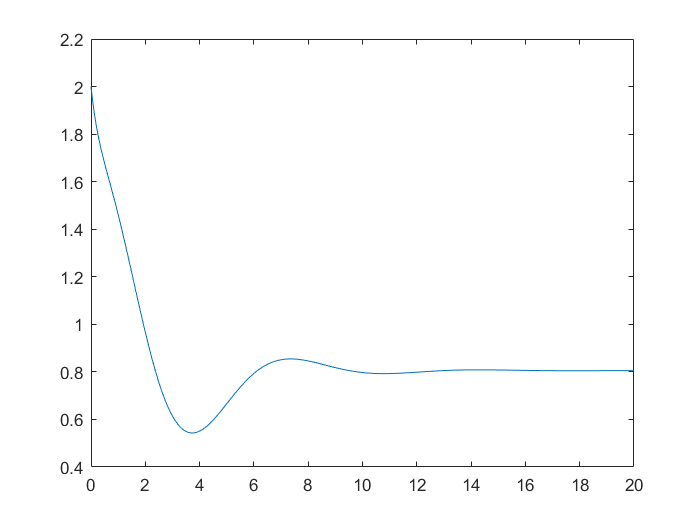

u = @(x1,x2,x3) -Kv(1)*x1 -Kv(2)*x2-Kv(3)*x3;

%x0 = [0.4;0.4;0.4];
tf = 20;
event_out = @(varargin) varargin{:};
x_lim = 30;
out_of_bounds = @(t,x) event_out(max(abs(x))-x_lim,1,1);
options = odeset('Events',out_of_bounds);
% for i=0:0.1:1
x0 = [0.1-0.6, 0, 0.1^0.5-0.6^0.5]';
sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
t = linspace(0,sol.x(end),500);
x = deval(sol,t);
u1(:) = u(x(1,:),x(2,:),x(3,:))+u0;
figure()
plot(t,u1(:))

It can be shown that  |𝑢(𝑡)|≤2 when $x(0)=[0.1,0,\sqrt{0.1}]$, so the controller satisfies the requirement.

2.3. Simulate the system under feedback control. Vary the initial condition as in Exercise 1.3. Remember to plot the original state $x_1(t)$ and not $y_1(t)$. Comment on the performance and the region of attraction.  

Solution: for $x(0)=(x_{1}, 0, \sqrt{x_{1}})$, vary $x_{1}$ from 0 to 0.7, with a step length 0.1, simulate the process and plot $x_{1}$, $x_{2}$ and $x_{3}$ with respect to time as below:

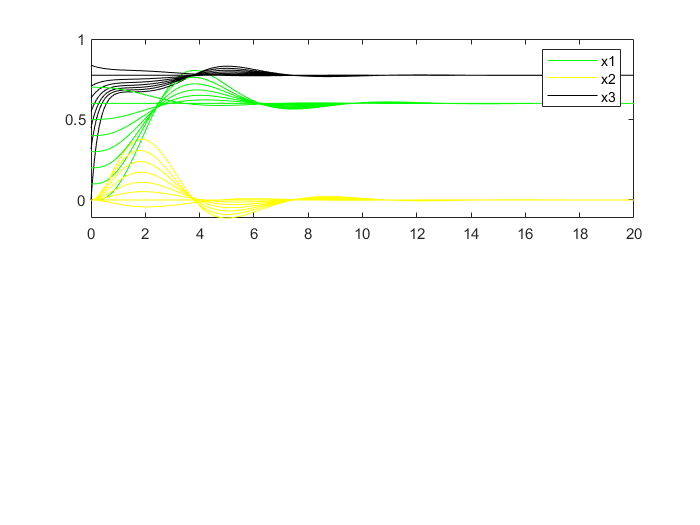

figure(4)
for i = 0:0.1:0.7
    x0 = [i-0.6, 0.0, i^0.5-0.6^0.5]';
    sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
    t = linspace(0,sol.x(end),500);
    x = deval(sol,t);
    subplot(2,1,1)
    plot(t,x(1,:)+0.6,'-g')
    hold on
    plot(t,x(2,:),'-y')
    hold on
    plot(t,x(3,:)+0.6^0.5,'-k')
    hold on
    legend('x1','x2','x3')
    hold on   
end

vary $x_{1}$ from 0.8 to 1.5, with a step length 0.1, simulate the process and plot $x_{1}$, $x_{2}$ and $x_{3}$ with respect to time as below:

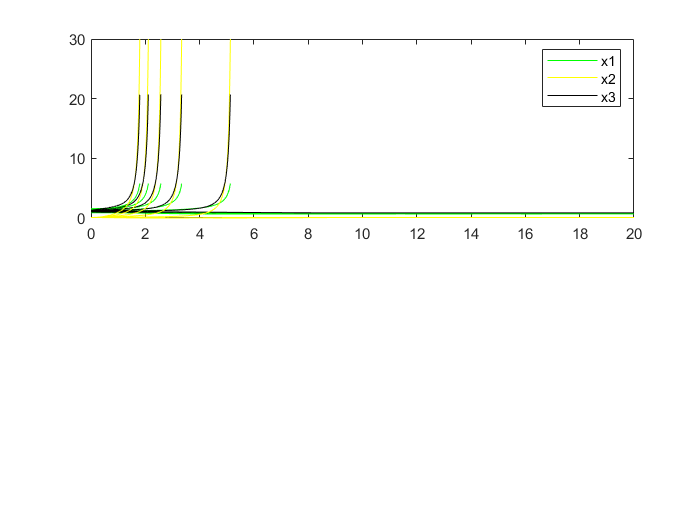

figure(41)
for i = 0.8:0.1:1.5
    x0 = [i-0.6, 0.0, i^0.5-0.6^0.5]';
    sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
    t = linspace(0,sol.x(end),500);
    x = deval(sol,t);
    subplot(2,1,1)
    plot(t,x(1,:)+0.6,'-g')
    hold on
    plot(t,x(2,:),'-y')
    hold on
    plot(t,x(3,:)+0.6^0.5,'-k')
    hold on
    legend('x1','x2','x3')
    hold on   
end

For $x_{3}^{*}=-\sqrt{0.6}$:

2.2. Design a controller using methods from linear control, for example pole placement ( `place(A,B,P) `) or LQR control ( `lqr(A,B,Q,R) `). Choose/tune the controller parameters so that $|u(t)| \leq 2$ when $x(0)=0$. A complete solution shall include the key steps of derivation of the controller and the numerical values of the controller.

Solution: We list the functions f1, f2 and f3, and calculate the Jacobian matrix A. Then, using function place(A,B,P), the controller gain Kv is calculated.

The poles we used are [-0.7;-0.4-0.9i;-0.4+0.9i].

syms x [3,1]
syms u
f1 = @(x1,x2,x3) x2;
f2 = @(x1,x2,x3) -x1-0.2*x2-2*sqrt(0.6).*x3 + x3.^2;
f3 = @(x1,x2,x3,u)  -2.6*sqrt(0.6)*x1+2.6*(0.6-1)*x3+2.6.*x1.*x3+u;
f = @(x1,x2,x3,u)[f1(x1,x2,x3);f2(x1,x2,x3);f3(x1,x2,x3,u)];
A = double(subs(jacobian(f,x),x,[0;0;0]));
B = [0;0;1];
u0 = -2.6*(1-0.6)*0.6^0.5

u0 = -0.8056

P = [-0.7;-0.4-0.9i;-0.4+0.9i];
Kv = place(A,B,P)

Kv =    -1.6131   -0.1743    0.2600


Then we can design the controller in the $u=-Kvx$ form.

for $x(0)=(0.1, 0, \sqrt{0.1})$, plot the control input u as below:

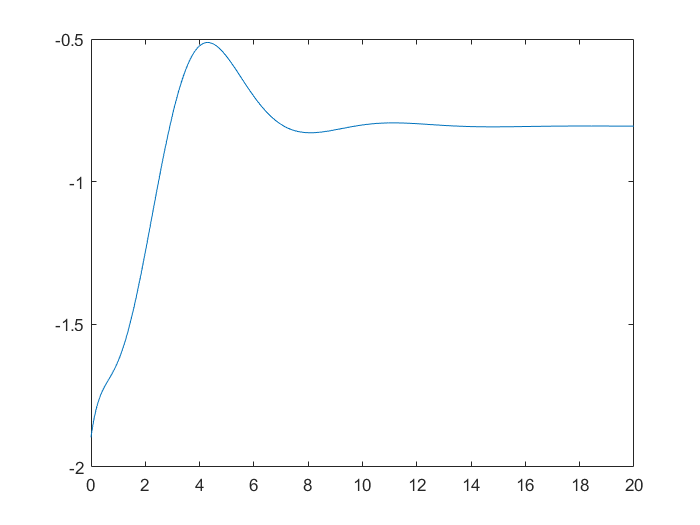

u = @(x1,x2,x3) -Kv(1)*x1 -Kv(2)*x2-Kv(3)*x3;

%x0 = [0.4;0.4;0.4];
tf = 20;
event_out = @(varargin) varargin{:};
x_lim = 30;
out_of_bounds = @(t,x) event_out(max(abs(x))-x_lim,1,1);
options = odeset('Events',out_of_bounds);
% for i=0:0.1:1
x0 = [0.1-0.6, 0, 0.1^0.5+0.6^0.5]';
sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
t = linspace(0,sol.x(end),500);
x = deval(sol,t);
u1(:) = u(x(1,:),x(2,:),x(3,:))+u0;
figure()
plot(t,u1(:))

It can be shown that  |𝑢(𝑡)|≤2 when $x(0)=[0.1,0,\sqrt{0.1}]$, so the controller satisfies the requirement.

2.3. Simulate the system under feedback control. Vary the initial condition as in Exercise 1.3. Remember to plot the original state $x_1(t)$ and not $y_1(t)$. Comment on the performance and the region of attraction.  

Solution: for $x(0)=(x_{1}, 0, \sqrt{x_{1}})$, vary $x_{1}$ from 0 to 0.7, with a step length 0.1, simulate the process and plot $x_{1}$, $x_{2}$ and $x_{3}$ with respect to time as below:

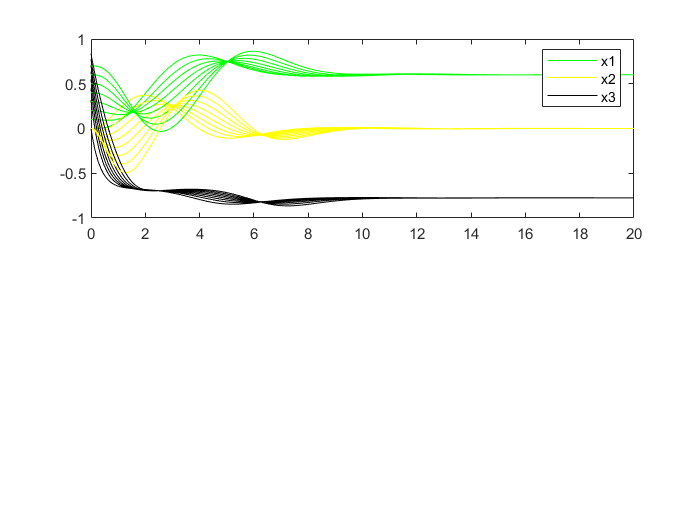

figure(5)
for i = 0:0.1:0.7
    x0 = [i-0.6, 0.0, i^0.5+0.6^0.5]';
    sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
    t = linspace(0,sol.x(end),500);
    x = deval(sol,t);
    subplot(2,1,1)
    plot(t,x(1,:)+0.6,'-g')
    hold on
    plot(t,x(2,:),'-y')
    hold on
    plot(t,x(3,:)-0.6^0.5,'-k')
    hold on
    legend('x1','x2','x3')
    hold on   
end

vary $x_{1}$ from 0.8 to 1.5, with a step length 0.1, simulate the process and plot $x_{1}$, $x_{2}$ and $x_{3}$ with respect to time as below:

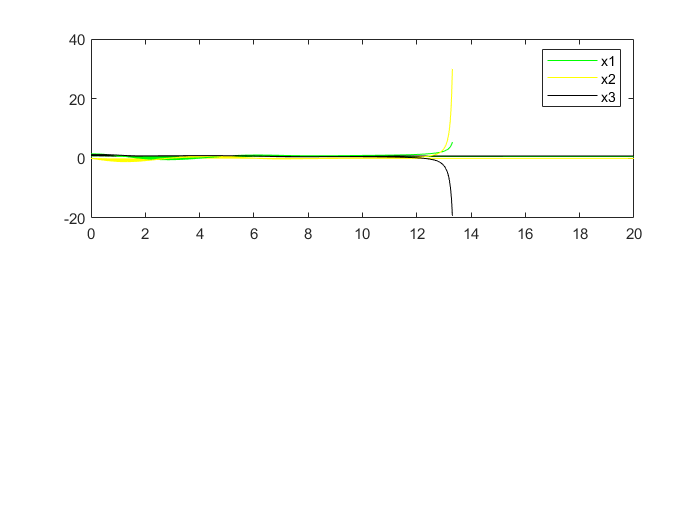

figure(51)
for i = 0.8:0.1:1.5
    x0 = [i-0.6, 0.0, i^0.5-0.6^0.5]';
    sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
    t = linspace(0,sol.x(end),500);
    x = deval(sol,t);
    subplot(2,1,1)
    plot(t,x(1,:)+0.6,'-g')
    hold on
    plot(t,x(2,:),'-y')
    hold on
    plot(t,x(3,:)+0.6^0.5,'-k')
    hold on
    legend('x1','x2','x3')
    hold on   
end

During the tuning, we find that if the poles are further from the imaginary axis, the region of attraction will be larger, but the initial abs(u) will become larger, causing more oscilation.

## Exercise 3：

### State Feedback Control

3.1. Verify that the system above is on controller form. What is $A$, $B$, $\psi(y)$and $\gamma(y)$? Is $(A, B)$ controllable? On what domain is $T$ invertible?

Solution:

The linearized state equation can be transformed into:


$$\left[ \begin{array}{ccc} \dot{z_1}\\ \dot{z_2}\\ \dot{z_3} \end{array}  \right ]=
\left[ \begin{array}{ccc} 0 & 1& 0\\ -1 & -b_2& 1\\ 0 & 0 & 0 \end{array}  \right ]\cdot  \left[ \begin{array}{ccc} z_1\\z_2\\ z_3 \end{array}  \right ] +\left[ \begin{array}{ccc} 0 \\ 0\\1 \end{array}\right ]\cdot [ (b_3+2y_3)\cdot(c_1\cdot y_1+c_3\cdot y_3+c_{13}y_1y_3)+(b_3+2y_3)v]


$$


 In this equation, there exists:


$$A=
\left[ \begin{array}{ccc} 0 & 1& 0\\ -1 & -b_2& 1\\ 0 & 0 & 0 \end{array}  \right ]
\\ B=\left[ \begin{array}{ccc} 0 \\ 0\\1 \end{array}\right ]
\\ \psi(y)=(b_3+2y_3)\cdot(c_1\cdot y_1+c_3\cdot y_3+c_{13}y_1y_3)
\\ \gamma(y)=b_3+2y_3$$


By calculating the controllability matrix ($R=\left[\begin{array}{lllll}
B & A B & A^{2} B 
\end{array}\right]$), we find that the controllability matrix is full rank. So $\left(A,B\right)$ is controllable.

R=[B, A*B, A*A*B]

rank(R)=3

A=[0 1 0; -1 -0.2 1; 0  0  0];
B=[0; 0; 1]

B =      0
     0
     1


R=[B, A*B, A*A*B]

R =          0         0    1.0000
         0    1.0000   -0.2000
    1.0000         0         0


rank(R)

ans = 3

For the third equation, plot the relation between y and z:

x3 = sqrt(0.6)

x3 = 0.7746

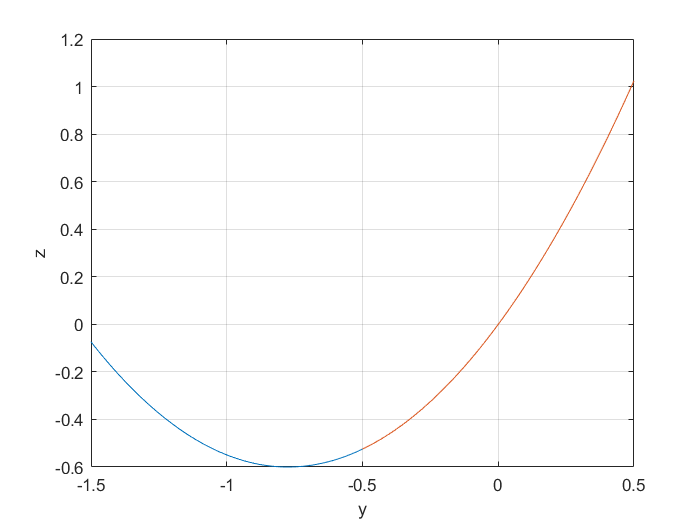

y = -1.5:0.01:0.5;
z = y .* (y+2*x3);
figure
plot(y,z)
grid on
hold on
m = -0.5:0.01:0.5;
n = m .* (m+2*x3);
plot(m,n)
xlabel('y')
ylabel('z')

So T is not globally invertible. But if $y_3 \ge -{x_3 }^*$ or $y_3 \le -{x_3 }^*$ ($x_3 \ge 0$ or $x_3 \le 0$) holds for the whole system running, we can regard the transformation $T$ as invertible.

3.2. Derive the feedback linearizing controller. For the linear part, follow the same procedure as you did in Exercise 2.2. Explain the main steps and write out the resulting controller. 

Solution:The process of deriving the linearizing controller:

In the first step, we can get the main form of the equation.


$$\left[ \begin{array}{ccc} \dot{z_1}\\ \dot{z_2}\\ \dot{z_3} \end{array}  \right ]=
\left[ \begin{array}{ccc} 0 & 1& 0\\ -1 & -b_2& 1\\ 0 & 0 & 0 \end{array}  \right ]\cdot  \left[ \begin{array}{ccc} z_1\\z_2\\ z_3 \end{array}  \right ] +\left[ \begin{array}{ccc} 0 \\ 0\\1 \end{array}\right ]\cdot [ (b_3+2y_3)\cdot(c_1\cdot y_1+c_3\cdot y_3+c_{13}y_1y_3)+(b_3+2y_3)u]


$$


And the we chose 


$$u=\frac{1}{(b_3+2y_3)} \cdot(-(b_3+2y_3)\cdot(c_1\cdot y_1+c_3\cdot y_3+c_{13}y_1y_3)+v)$$


Then the system is transformed into


$$\left[ \begin{array}{ccc} \dot{z_1}\\ \dot{z_2}\\ \dot{z_3} \end{array}  \right ]=
\left[ \begin{array}{ccc} 0 & 1& 0\\ -1 & -b_2& 1\\ 0 & 0 & 0 \end{array}  \right ]\cdot  \left[ \begin{array}{ccc} z_1\\z_2\\ z_3 \end{array}  \right ] +\left[ \begin{array}{ccc} 0 \\ 0\\1 \end{array}\right ]\cdot v


$$


Because (A, B) is controllable, so we can chose


$$v=-k\cdot z$$


So the final form can be expressed as 


$$u=\frac{1}{(b_3+2y_3)} \cdot(-(b_3+2y_3)\cdot(c_1\cdot y_1+c_3\cdot y_3+c_{13}y_1y_3)-KT(y))$$


where


$$z=T(y)=\left[ \begin{array}{ccc} y_1\\ y_2 \\ b_3y_3+y_3^2  \end{array}  \right ]$$


3.3 Simulate the system from different initial conditions like in Exercise 2.3. 

Solution:

change the initial condition from 0-1 of x1,and the initial state is defined as


$$x(0)=\left[ \begin{array}{ccc} x_1(0)&0&\sqrt{x_1(0)} \end{array}  \right ]$$


The simulation results is shown as:

-  when $x_3^*=\sqrt{0.6
}$

From this figure we can see that the state will converge when the intial value change between [0  2], so we can prove that it is a stable system.

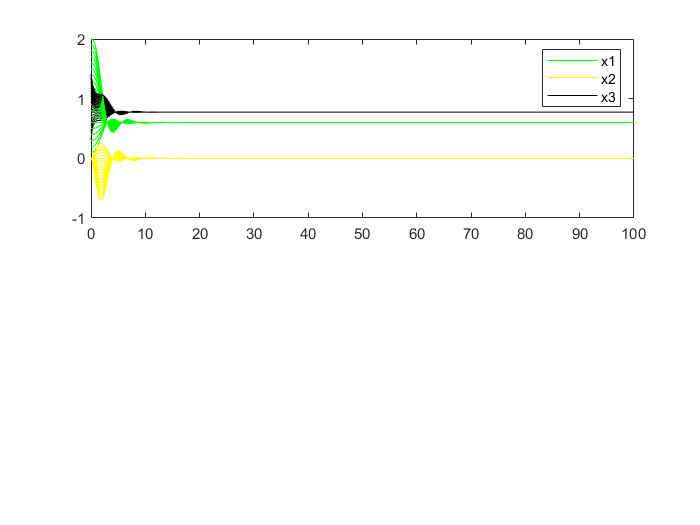

f1 = @(x1,x2,x3) x2;
f2 = @(x1,x2,x3) -x1-b2*x2+b31.*x3 + x3.^2;
f3 = @(x1,x2,x3,u)  c11*x1+c3*x3+c13.*x1.*x3+u;
f = @(x1,x2,x3,u)[f1(x1,x2,x3);f2(x1,x2,x3);f3(x1,x2,x3,u)];
psi = @(x1,x2,x3)(b31+2.*x3)*(c11.*x1+c3.*x3+c13.*x1.*x3);
gamma = @(x1,x2,x3)(b31+2.*x3);
A =[0 1 0; -1 -0.2 1; 0  0  0];
B =[0; 0; 1];
Q = eye(3);
R = 1;
Kv = lqr(A,B,Q,R);
v = @(x1,x2,x3) -Kv(1)*x1 -Kv(2)*x2-Kv(3)*(b31*x3+x3^2);
u_fbl = @(x1,x2,x3) 1./gamma(x1,x2,x3).*(-psi(x1,x2,x3)+v(x1,x2,x3));
figure()
%x0 = [0.4;0.4;0.4];
tf = 100;
event_out = @(varargin) varargin{:};
x_lim = 30;
out_of_bounds = @(t,x) event_out(max(abs(x))-x_lim,1,1);
options = odeset('Events',out_of_bounds);
figure(6)
for i=0:0.1:2
    x0 = [i-0.6, 0, i^0.5-0.6^0.5]';
u = u_fbl;
 
    sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
    t = linspace(0,sol.x(end),500);
    x = deval(sol,t);
    figure(6)
    subplot(2,1,1)
    plot(t,x(1,:)+0.6,'-g')
    hold on
    plot(t,x(2,:),'-y')
    hold on
    plot(t,x(3,:)+0.6^0.5,'-k')
    hold on
    legend('x1','x2','x3')
%     subplot(2,1,2)
%     plot(t,u{:},(x(1,:),x(2
end

2. when $x_3^*=-\sqrt{0.6
}$

From this figure we can see that the state will converge when the intial value change between [0  2], so we can prove that it is a stable system.

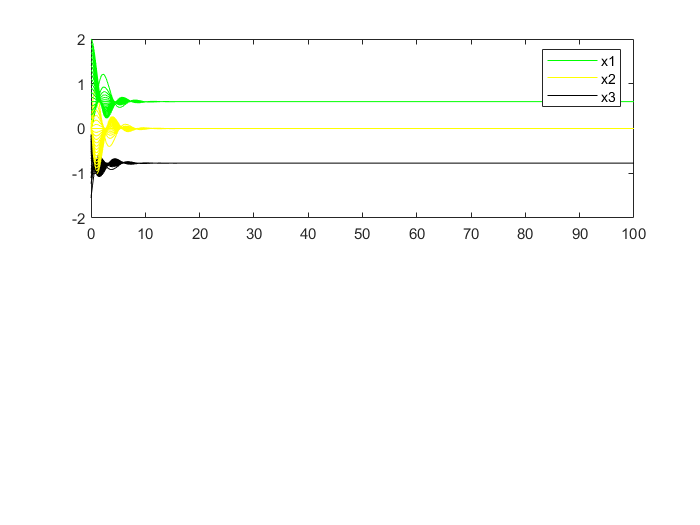

f1 = @(x1,x2,x3) x2;
f2 = @(x1,x2,x3) -x1-b2*x2+b32.*x3 + x3.^2;
f3 = @(x1,x2,x3,u)  c12*x1+c3*x3+c13.*x1.*x3+u;
f = @(x1,x2,x3,u)[f1(x1,x2,x3);f2(x1,x2,x3);f3(x1,x2,x3,u)];
psi = @(x1,x2,x3)(b32+2.*x3)*(c12.*x1+c3.*x3+c13.*x1.*x3);
gamma = @(x1,x2,x3)(b32+2.*x3);
A =[0 1 0; -1 -0.2 1; 0  0  0];
B =[0; 0; 1];
Q = eye(3);
R = 1;
Kv = lqr(A,B,Q,R);
v = @(x1,x2,x3) -Kv(1)*x1 -Kv(2)*x2-Kv(3)*(b32*x3+x3^2);
u_fbl = @(x1,x2,x3) 1./gamma(x1,x2,x3).*(-psi(x1,x2,x3)+v(x1,x2,x3));
%x0 = [0.4;0.4;0.4];
tf = 100;
event_out = @(varargin) varargin{:};
x_lim = 30;
out_of_bounds = @(t,x) event_out(max(abs(x))-x_lim,1,1);
options = odeset('Events',out_of_bounds);
figure(7)
for i=0:0.1:2
    x0 = [i-0.6, 0, i^0.5-0.6^0.5]';
u = u_fbl;
 
    sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
    t = linspace(0,sol.x(end),500);
    x = deval(sol,t);
    figure(7)
    subplot(2,1,1)
    plot(t,x(1,:)+0.6,'-g')
    hold on
    plot(t,x(2,:),'-y')
    hold on
    plot(t,x(3,:)-0.6^0.5,'-k')
    hold on
    legend('x1','x2','x3')
%     subplot(2,1,2)
%     plot(t,u{:},(x(1,:),x(2
end



%matlab Function
% function dx=systemt(t,x)
% dx(1,1)=x(2);
% dx(2,1)=-x(1)-0.2*x(2)+x(3)^2;
% dx(3,1)=-2.6*(1-x(1))*x(3)+0.8;
% end % The state Space Equation
